# Locally Weighted Scatterplot Smoothing

A program which is developed based on lowess approach for smoothing rate-normalized pressure (RNP) data.

Author: Munthe, Felix A.

Created on Monday, 30 October 2023

## Import Data

### True RNP Data

clear; clc; clf;
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
true_RNP = readtable("C:\Users\felix\OneDrive\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\true_RNP.txt", opts)

true_RNP = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.3616e+06
    0.33041    1.9565e+06
     0.4862    2.6089e+06
    0.79777    3.4782e+06
     1.4209    4.6953e+06
     2.6672    6.4232e+06
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    1.7054e+07
     35.645    2.3347e+07
      66.06    3.1893e+07
     124.99    4.3906e+07
     188.99    5.4925e+07
     252.99    6.4572e+07
     316.99    7.3193e+07
     380.99     8.103e+07


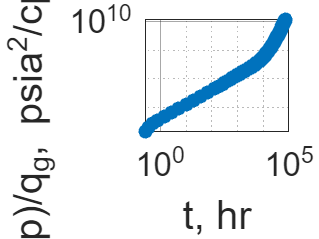


% Plot
loglog(true_RNP.t, true_RNP.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("True RNP Data", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
%xlim([3 3000000]);
%ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

### Noisy RNP Data Set 199

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
noisy_RNP_199 = readtable("C:\Users\felix\OneDrive\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\Noisy RNP Model\All\50%\noisy_data_9.txt", opts)

noisy_RNP_199 = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.3616e+06
    0.33041    1.9565e+06
     0.4862    2.6089e+06
    0.79777    3.4782e+06
     1.4209    4.6953e+06
     2.6672    1.2191e+08
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    1.7054e+07
     35.645    2.2503e+07
      66.06    2.4622e+08
     124.99    4.3906e+07
     188.99    2.7921e+08
     252.99    6.4572e+07
     316.99     1.289e+08
     380.99     8.103e+07


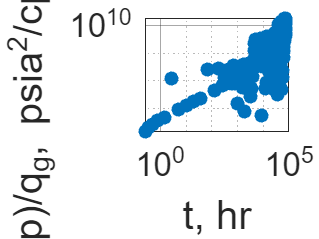


% Plot
loglog(noisy_RNP_199.t, noisy_RNP_199.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("Noisy RNP Data Set 199", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
%xlim([3 3000000]);
%ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

## Smoothing

### Noisy RNP Data 199

logRNP_199 = log(noisy_RNP_199.RNP);

#### Window: 3

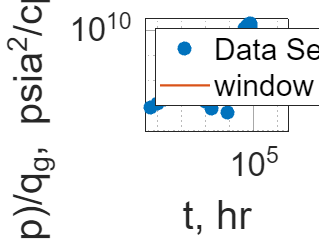

% Plot
loglog(noisy_RNP_199.t, noisy_RNP_199.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 199");
% title("Noisy RNP Data Set 199", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_199_31 = smooth(logRNP_199, 3, "lowess");
smoothedRNP_199_31 = exp(smoothedLogRNP_199_31);
residual_199_31 = (true_RNP.RNP - smoothedRNP_199_31) ./ (0.3413 .* true_RNP.RNP);
sse_199_31 = sum(residual_199_31 .^ 2);
loglog(noisy_RNP_199.t, smoothedRNP_199_31, "-", "LineWidth", 1.3, "DisplayName", "window = 3");
legend("Location", "northwest");
hold off;

### Window: 5

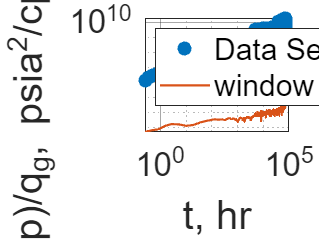

% Plot
loglog(noisy_RNP_199.t, noisy_RNP_199.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 199");
% title("Noisy RNP Data Set 199", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
%xlim([3 3000000]);
%ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_199_51 = smooth(logRNP_199, 5, "lowess");
smoothedRNP_199_51 = exp(smoothedLogRNP_199_51);
residual_199_51 = (true_RNP.RNP - smoothedRNP_199_51) ./ (0.3413 .* true_RNP.RNP);
sse_199_51 = sum(residual_199_51 .^ 2);
loglog(noisy_RNP_199.t, smoothedRNP_199_51, "-", "LineWidth", 1.3, "DisplayName", "window = 5");
legend("Location", "northwest");
hold off;

#### Window: 7

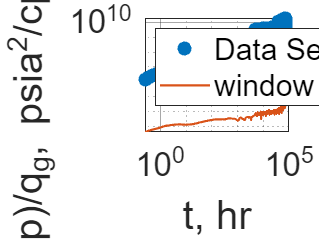

% Plot
loglog(noisy_RNP_199.t, noisy_RNP_199.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 199");
% title("Noisy RNP Data Set 199", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
%xlim([3 3000000]);
%ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_199_71 = smooth(logRNP_199, 7, "lowess");
smoothedRNP_199_71 = exp(smoothedLogRNP_199_71);
residual_199_71 = (true_RNP.RNP - smoothedRNP_199_71) ./ (0.3413 .* true_RNP.RNP);
sse_199_71 = sum(residual_199_71 .^ 2);
loglog(noisy_RNP_199.t, smoothedRNP_199_71, "-", "LineWidth", 1.3, "DisplayName", "window = 7");
legend("Location", "northwest");
hold off;

#### Window: 9

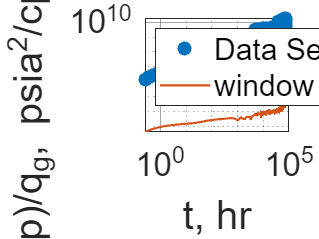

% Plot
loglog(noisy_RNP_199.t, noisy_RNP_199.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 199");
% title("Noisy RNP Data Set 199", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
%xlim([3 3000000]);
%ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_199_91 = smooth(logRNP_199, 9, "lowess");
smoothedRNP_199_91 = exp(smoothedLogRNP_199_91);
residual_199_91 = (true_RNP.RNP - smoothedRNP_199_91) ./ (0.3413 .* true_RNP.RNP);
sse_199_91 = sum(residual_199_91 .^ 2);
loglog(noisy_RNP_199.t, smoothedRNP_199_91, "-", "LineWidth", 1.3, "DisplayName", "window = 9");
legend("Location", "northwest");
hold off;

#### Window: 11

% Plot
loglog(noisy_RNP_199.t, noisy_RNP_199.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 199");
% title("Noisy RNP Data Set 199", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_199_111 = smooth(logRNP_199, 11, "lowess");
smoothedRNP_199_111 = exp(smoothedLogRNP_199_111);
residual_199_111 = (true_RNP.RNP - smoothedRNP_199_111) ./ (0.3413 .* true_RNP.RNP);
sse_199_111 = sum(residual_199_111 .^ 2);
loglog(noisy_RNP_199.t, smoothedRNP_199_111, "-", "LineWidth", 1.3, "DisplayName", "window = 11");
legend("Location", "northwest");
hold off;

#### Window: 13

% Plot
loglog(noisy_RNP_199.t, noisy_RNP_199.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 199");
% title("Noisy RNP Data Set 199", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_199_131 = smooth(logRNP_199, 13, "lowess");
smoothedRNP_199_131 = exp(smoothedLogRNP_199_131);
residual_199_131 = (true_RNP.RNP - smoothedRNP_199_131) ./ (0.3413 .* true_RNP.RNP);
sse_199_131 = sum(residual_199_131 .^ 2);
loglog(noisy_RNP_199.t, smoothedRNP_199_131, "-", "LineWidth", 1.3, "DisplayName", "window = 13");
legend("Location", "northwest");
hold off;

#### Window: 15

% Plot
loglog(noisy_RNP_199.t, noisy_RNP_199.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 199");
% title("Noisy RNP Data Set 199", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_199_151 = smooth(logRNP_199, 15, "lowess");
smoothedRNP_199_151 = exp(smoothedLogRNP_199_151);
residual_199_151 = (true_RNP.RNP - smoothedRNP_199_151) ./ (0.3413 .* true_RNP.RNP);
sse_199_151 = sum(residual_199_151 .^ 2);
loglog(noisy_RNP_199.t, smoothedRNP_199_151, "-", "LineWidth", 1.3, "DisplayName", "window = 15");
legend("Location", "northwest");
hold off;

#### Window: 17

% Plot
loglog(noisy_RNP_199.t, noisy_RNP_199.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 199");
% title("Noisy RNP Data Set 199", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_199_171 = smooth(logRNP_199, 17, "lowess");
smoothedRNP_199_171 = exp(smoothedLogRNP_199_171);
residual_199_171 = (true_RNP.RNP - smoothedRNP_199_171) ./ (0.3413 .* true_RNP.RNP);
sse_199_171 = sum(residual_199_171 .^ 2);
loglog(noisy_RNP_199.t, smoothedRNP_199_171, "-", "LineWidth", 1.3, "DisplayName", "window = 17");
legend("Location", "northwest");
hold off;

#### Window: 19

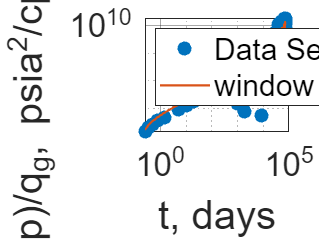

% Plot
loglog(noisy_RNP_199.t, noisy_RNP_199.RNP, ".", "MarkerSize", 25, "Color", "#0072BD", "DisplayName", "Data Set 199");
% title("Noisy RNP Data Set 199", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, days", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
%xlim([3 3000000]);
%ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_199_191 = smooth(logRNP_199, 19, "lowess");
smoothedRNP_199_191 = exp(smoothedLogRNP_199_191);
residual_199_191 = (true_RNP.RNP - smoothedRNP_199_191) ./ (0.3413 .* true_RNP.RNP);
sse_199_191 = sum(residual_199_191 .^ 2);
loglog(noisy_RNP_199.t, smoothedRNP_199_191, "-", "LineWidth", 1.3, "DisplayName", "window = 19");
legend("Location", "northwest");
hold off;